# Modeling a Pendulum

[⇦ Overview](matlab: OpenOverview)

**Before you get started:**

This live script is intended to be used with the code visible for interaction. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**.  Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one because this script will not run until you have written some necessary code to create the models as directed.

The first physical model of a pendulum that you encounter is the simple harmonic pendulum of length $L$ based on Newton's second law for rotational systems, 

$\tau = I\alpha$,

where $\tau$ is the torque, $I=mL^2$ is the rotational moment of inertia, and $\alpha = \frac{d^2\theta}{dt^2}$ is the angular acceleration. The small angle approximations $\cos(\theta) \approx 1$ and $\sin(\theta) \approx \theta$ are used to linearize the system.  

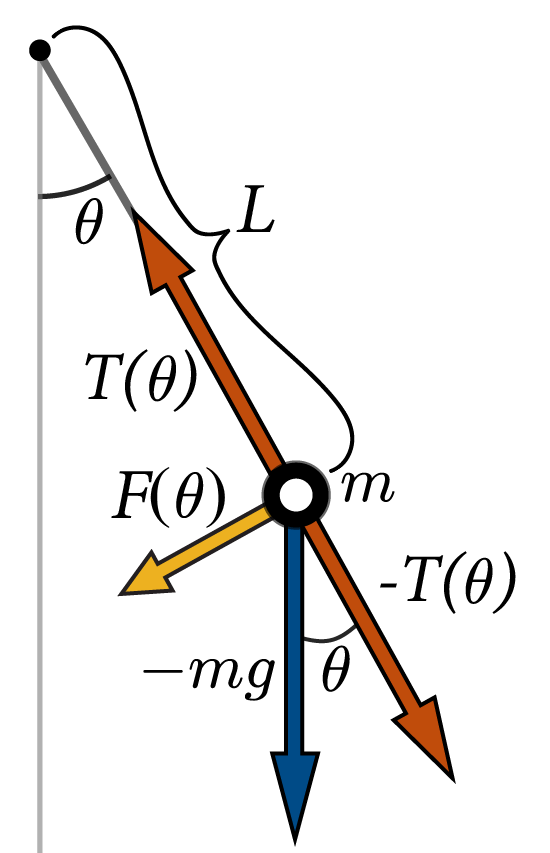

In this diagram, $T(\theta)$ is the tension force on the support of the pendulum, $m$ is the mass of the pendulum, $g$ is acceleration due to gravity, and $F(\theta)$ is the net force on the pendulum. Combining these values as shown, $F(\theta) = -mg\sin(\theta)$ and therefore $\tau = -mg\sin(\theta)L$. Putting this together, we have

$-mg\sin(\theta)L = mL^2\frac{d^2\theta}{dt^2}$, 

which can be linearized with the small angle approximation $\sin(\theta) \approx \theta$ and simplified into the simple harmonic motion equation:

        $\frac{d^2\theta}{dt^2} = -\frac{g}{L}\theta$,        $(\star)$

where $L$ is the length of your pendulum, $g$ is the acceleration due to gravity, $\theta$ is the angle from the vertical, and $t$ is time. 

L = 1.4;         % meters
g = 9.80665;     % m/s^2, exact
theta0 = pi/4;   % radians initial angle
omega0 = 0;      % rad/sec initial angular velocity
t0 = 0;          % initial time
tEnd = 30;       % end time

  **Try**. Use `ode45` to implement model $(\star)$ using the function `model1`. All angles are given in radians.

- Test with `theta0 = pi/16`

- Test with `theta0 = pi/4`

- Test with `theta0 = pi/2`

- Test with `theta0 = pi`

- Test with` theta0 = 3.1416;`

Compare this to your expectations for a physical pendulum. Do you see any obvious problems with this model with these values for `theta0`?

[t1,theta1] = ode45(@(t,theta) model1(t,theta,L,g),[t0 tEnd],[theta0 omega0]);
plot(t1,theta1(:,1))
title("Model of a simple harmonic pendulum")
subtitle("$L\ddot{\theta} = -g\theta$","Interpreter","latex")
yticklabels(["-\pi" "-\pi/2" "-\pi/4" "-\pi/16" "0" "\pi/16" "\pi/4" "\pi/2" "\pi"])
yticks([-pi -pi/2 -pi/4 -pi/16 0 pi/16 pi/4 pi/2 pi])
ylabel("Angle (rad)")
xlabel("Time (s)")

### Consider Measurement Error

In any physical system, it is expected that there will be some measurement errors introduced when trying to describe the system. How much do such errors impact the results of your model? What are reasonable values to assume for the errors in each of these measurements with the tools you have access to?

tEnd = 4;                               % Set a shorter end time to make it easier to see the variation
Lerror =0.005;   % error in length measurement in meters
angError =0.01;  % error in angle measurement in radians
velError =0.1;  % error in angular velocity measurement in rad/sec

% Calculate the solution
[t1,theta1] = ode45(@(t,theta) model1(t,theta,L,g),[t0 tEnd],[theta0 omega0]);

% Add error in the measurement of the length of the pendulum
[t1Errp,theta4Ep] = ode45(@(t,theta) model1(t,theta,L+Lerror,g),[t0 tEnd],[theta0+angError omega0+velError]);
[t1Errm,theta4Em] = ode45(@(t,theta) model1(t,theta,L-Lerror,g),[t0 tEnd],[theta0-angError omega0-velError]);

% Plot the model with no errors and compare to the models with errors
plot(t1,theta1(:,1))
hold on
plot(t1Errp,theta4Ep(:,1),"--","SeriesIndex",2)
plot(t1Errm,theta4Em(:,1),":","SeriesIndex",3)
hold off

% Label the plot
title("Model of a simple harmonic pendulum")
subtitle("Error $\Delta L = \pm$" + Lerror + ", $\Delta \theta_0 = \pm$" + angError + ...
    ", and $\Delta \alpha_0 = \pm$" + velError,"Interpreter","latex")
yticklabels(["-\pi" "-\pi/2" "-\pi/4" "-\pi/16" "0" "\pi/16" "\pi/4" "\pi/2" "\pi"])
yticks([-pi -pi/2 -pi/4 -pi/16 0 pi/16 pi/4 pi/2 pi])
ylabel("Angle (rad)")
xlabel("Time (s)")
legend("No Error", "Adding Error", "Subtracting Error","Location","southoutside")

## Improve the model by allowing nonlinearity

We can improve this by acknowledging that the gravitational forcing term was a linearization. More accurately, the equation modeling a simple pendulum is:

        $mL^2\frac{d^2\theta}{dt^2} = -mgL\sin(\theta)$,         $(\star \star)$

where $mL^2$ is the rotational moment of inertia and $mgL\sin(\theta)$ is the torque on the pendulum. 

  **Try**. Use `ode45` to implement this model using the function `model2`. Then plot the results of both models together. For which values of the parameters are they close? When do they begin to diverge? Compare model $(\star \star)$ to your expectations for a physical pendulum.

Note: `model2` must be written before you run this code or you will get errors.  

% Reset to a longer tEnd to see more impact over time
tEnd = 30;      % time in seconds

% Solve the nonlinear model
[t2,theta2] = ode45(@(t,theta) model2(t,theta,L,g),[t0 tEnd],[theta0 omega0]);

% Select the checkbox to plot the linear model and nonlinear model together
showModel1 = true;
% Set the series index for color consistency across all the graphs independent of
% order of plotting
plot(t2,theta2(:,1),"SeriesIndex",2)
if showModel1
    hold on
    plot(t1,theta1(:,1),"SeriesIndex",1)
    hold off
end
legendTextOpts = "$\star$" ;
legend(["$\star \star$" legendTextOpts(showModel1)],"Interpreter","latex","Location","southoutside")
title("Model of a simple pendulum")
subtitle("$L\ddot{\theta} = -g\sin(\theta)$","Interpreter","latex")

## Model including drag

We also discussed the importance of drag in a model of an object, even if it is moving through air. Let

     $mL^2\frac{d^2\theta}{dt^2} = -b\frac{d\theta}{dt}\pm c\left(\frac{d\theta}{dt}\right)^2-mgL\sin(\theta)$,     $(\star \star \star)$

where $b$ and $c$ are drag coefficients. 

b = .02;
c = .06;
M = 5;           % kg

  **Try**. Use `ode45` to implement model $(\star \star \star)$ using the function `model3`. Then plot the results of all three models together. For which values of the parameters are they close? When do they begin to diverge? Compare model $(\star \star \star)$ to your expectations for a physical pendulum. 

Note: `model3` must be written before you run this code or you will get errors.

 As you increase the value of `c`, you should observe damping in your model. If you do not, check that the term $c\left(\frac{d\theta}{dt}\right)^2$ is always acting against the motion $\frac{d\theta}{dt}$ for $c>0$. 

% Solve model 3 with damping
[t3,theta3] = ode45(@(t,theta) model3(t,theta,L,g,M,b,c),[t0 tEnd],[theta0 omega0]);

% Select the checkbox for each model you want to plot with model 3
showModel1 = false;
showModel2 = true;
plot(t3,theta3(:,1),"SeriesIndex",3)

if showModel1
    hold on  
    plot(t1,theta1(:,1),"SeriesIndex",1)
    hold off
end
if showModel2
    hold on
    plot(t2,theta2(:,1),"SeriesIndex",2)
    hold off
end
legendTextOpts = ["$\star$" "$\star \star$"] ;
legend(["$\star \star \star$" legendTextOpts([showModel1 showModel2])],"Interpreter","latex","Location","southoutside")
title("Modeling a pendulum")
subtitle("$mL^2\ddot{\theta} = -b\dot{\theta}\pm c \left(\dot{\theta}\right)^2-mgL\sin(\theta)$","Interpreter","latex")

## Improve the model by adding the mass of the bar

Finally, we could acknowledge that the pendulum is not an ideal mass at a distance of $L$ from the pivot, but there is a mass, $m$, associated with the bar and the mass, $M$, of the pendulum weight. We shall continue to use $L$ to be the distance from the pivot point to the center of mass of the pendulum weight. Working in terms of the more carefully calculated moment and including the mass of the bar at a center of mass $\frac{L}{2}$, we have

$\left(m\frac{L^2}{3} + ML^2\right)\frac{d^2\theta}{dt^2} = g\left(ML+\frac{mL}{2}\right)\sin(\theta)-b\frac{d\theta}{dt}\pm c\left(\frac{d\theta}{dt}\right)^2$.    $(\star \star \star \star)$

rho = 0.79;     % kg/m
m = rho*L;      % kg

  **Try**. Use `ode45` to implement model $(\star \star \star \star)$ using the function `model4`. Then plot the results of all four models together. You may want to use [`xlim`](matlab: doc xlim) to focus on a section of the plot to look for differences between the models.

Note: `model4` must be written before you run this code or you will get errors.

- Test with `rho = 0.01 `kg/m, as for light nylon rope

- Test with `rho = 0.15 `kg/m, as for a thin wooden bar

- Test with `rho = 0.79 `kg/m, as for an iron chain

- Test with `m = 100`

For which values of the parameters are they close? When do they begin to diverge? Compare model $(\star \star \star \star)$ to your expectations for a physical pendulum. 

% Solve model 4, including the mass of the support bar
[t4,theta4] = ode45(@(t,theta) model4(t,theta,L,g,M,m,b,c),[t0 tEnd],[theta0 omega0]);

plot(t4,theta4(:,1),"SeriesIndex",4)

% Select the checkbox for each model you want to plot with model 4
showModel1 = false;
showModel2 = false;
showModel3 = true;

if showModel1
    hold on
    plot(t1,theta1(:,1),"SeriesIndex",1)
    hold off
end
if showModel2
    hold on
    plot(t2,theta2(:,1),"SeriesIndex",2)
    hold off
end
if showModel3
    hold on
    plot(t3,theta3(:,1),"SeriesIndex",3)
    hold off
end
legendTextOpts = ["$\star$" "$\star \star$" "$\star \star \star$"] ;
legend(["$\star \star \star \star$" legendTextOpts([showModel1 showModel2 showModel3])], ...
    "Interpreter","latex","Location","southoutside")
title("Modeling a pendulum")
subtitle("$\left(\frac{m}{3}L^2+ML^2\right)\ddot{\theta} = -b\dot{\theta}\pm c " + ...
    "\left(\dot{\theta}\right)^2-g\left(ML+\frac{mL}{2}\right)\sin(\theta)$","Interpreter","latex")

plot(t1,theta1(:,1),t2,theta2(:,1),t3,theta3(:,1),t4,theta4(:,1))
title("Four models of a simple pendulum")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend(["$\star$" "$\star \star$" ...
    "$\star \star \star$" ...
    "$\star \star \star \star$"],"Interpreter","latex","Location","southoutside")
xlim([tEnd-2 tEnd])

 **Reflect**.

- What does each additional term do to the period of the model pendulum? 

- What about the amplitude of the model pendulum? 

- Do you believe that the models are increasingly realistic? Why or why not?

- How could you test your models?

## Considering Error

Copy the code from Consider Measurement Error and adapt it to apply to Model $\star \star \star \star$. What do you see?

[⇦ Overview](matlab: OpenOverview)

## Models

#### Model 1 

Return to use `model1`.


$$\frac{d^2\theta}{dt^2} = -\frac{g}{L}\theta$$


function dydt = model1(t,y,L,g)
theta = y(1);
omega = y(2);
dydt = [omega; ...
    -g/L*theta];
end

#### Model 2

Return to use `model2`.


$$ML^2\frac{d^2\theta}{dt^2} = -gML\sin(\theta)$$
 

function dydt = model2(t,y,L,g)

end

#### Model 3

Return to use `model3`.

$ML^2\frac{d^2\theta}{dt^2} = -b\frac{d\theta}{dt}\pm c\left(\frac{d\theta}{dt}\right)^2-gML\sin(\theta)$,

function dydt = model3(t,y,L,g,M,b,c)

end

#### Model 4

Return to use `model4`.


$$\left(m\frac{L^2}{3} + ML^2\right)\frac{d^2\theta}{dt^2} = g\left(ML+\frac{mL}{2}\right)\sin(\theta)-b\frac{d\theta}{dt}\pm c\left(\frac{d\theta}{dt}\right)^2$$


function dydt = model4(t,y,L,g,M,m,b,c)

end

% Suppress warning about unused variable t in the model functions
%#ok<*INUSL>
% Suppress warning about inaccessible code due to checkbox interactions
%#ok<*UNRCH>